N=12000;
rollVals=randi(6,[N,1])

rollVals =      1
     6
     6
     3
     4
     2
     4
     1
     3
     6


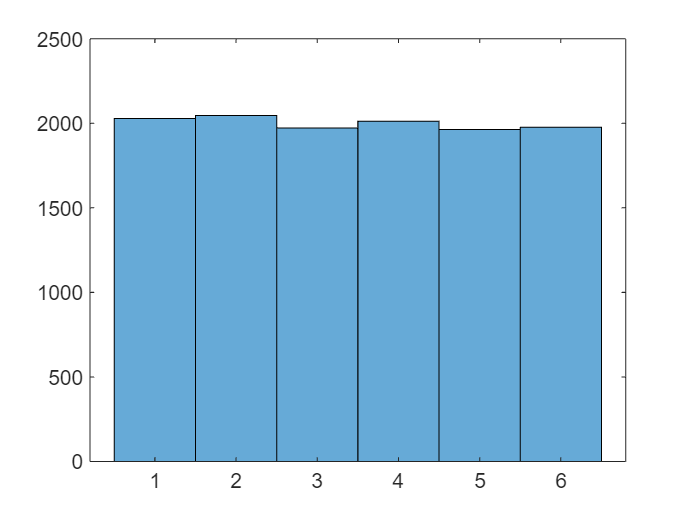

histogram(rollVals)

flights=importFlightsData("flightsFeb.csv");
flights=rmmissing(flights,'DataVariables',{'ACTUAL_ELAPSED_TIME','SCHEDULED_ELAPSED_TIME'});
flights.DURATION_DIFF=flights.ACTUAL_ELAPSED_TIME-flights.SCHEDULED_ELAPSED_TIME;

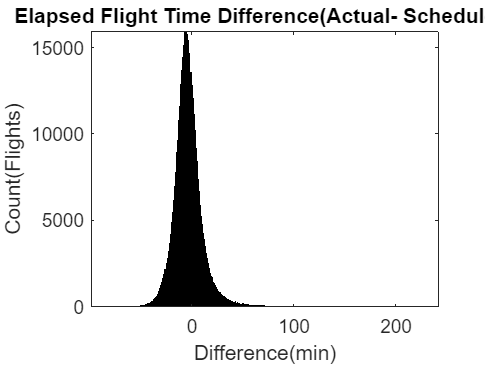

histogram(flights.DURATION_DIFF)
title("Elapsed Flight Time Difference(Actual- Scheduled)")
ylabel("Count(Flights)");
xlabel("Difference(min)")

avg=mean((flights.DURATION_DIFF))

avg = -3.4552

sd=std((flights.DURATION_DIFF))

sd = 14.6626

[avg-sd avg+sd]

ans =   -18.1178   11.2074


kt=kurtosis(rmmissing(flights.DURATION_DIFF))%bağlılık  

kt = 14.3533

sk=skewness(rmmissing(flights.DURATION_DIFF))%eğrilik

sk = 1.8145

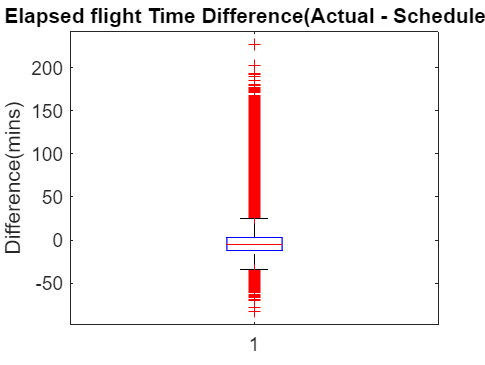

boxplot(flights.DURATION_DIFF);
title("Elapsed flight Time Difference(Actual - Scheduled)")
ylabel("Difference(mins)")